% loads data sets

set1 = load('../dat/1_9kb_final/nucleus_struct2.mat');
set2 = load('../dat/2_65kb_final/nucleus_struct2.mat');
set3 = load('../dat/3_4kb_final/nucleus_struct2.mat');
set3_2 = load('../dat/3_4_pass2/nucleus_struct.mat');
Gt_test = load('../dat/Gt_test/nucleus_struct.mat');
set_new = load('../dat/3_4kb_new1/nucleus_struct.mat');
set_new2 = load('../dat/3_4kb_testset4_2/nucleus_struct.mat');
set_new3 = load('../dat/2_65kb_new/nucleus_struct.mat');
high_thresh3 = load('../dat/3_4kb_highthresh/nucleus_struct.mat');
high_thresh2 = load('../dat/2_65kb_highthresh/nucleus_struct.mat');

% Pick out a subset of data
nc = 14;
nucleus_struct = high_thresh3.nucleus_struct;

subset = nucleus_struct([nucleus_struct.ncStart] == nc);
%subset = subset([subset.setID] == 3);
display(median(diff([subset.time_interp])));

    11




sub1 = set1.nucleus_struct([set1.nucleus_struct.ncStart] == nc);
sub2 = set2.nucleus_struct([set2.nucleus_struct.ncStart] == nc);
sub3 = set3.nucleus_struct([set3.nucleus_struct.ncStart] == nc);

% Run autocorrelation on subset of data
sum_all = zeros(1, 600);
idxes = zeros(1, 600);
traces = {};
min_trace = 100;
idx = 1;
field = 'fluo3D_interp';
start_times= [];
for s = subset
    if sum(isnan(s.(field))) == 0 && s.inference_flag
        marks = find(s.(field) < 10);
        marks = [1 marks length(s.(field))];
        for i = 2:length(marks)
            if marks(i) - marks(i - 1) > min_trace
                first = marks(i-1) + 15;
                last = marks(i) - 15;
                traces{idx} = s.(field)(first:1:last);
                %idx = idx + 1;
                %traces{idx} = s.(field)((first + 1):2:last);
                %idx = idx + 1;
                %traces{idx} = s.(field)((first + 2):3:last);
                len = length(traces{idx});
                sum_all(1:len) = sum_all(1:len) + traces{idx};
                idxes(1:len) = idxes(1:len) + 1;
                idx = idx + 1;
                start_times = [start_times s.time_interp(first)];
            end
        end
    end
end

gen_auto_cor(traces, 0:2, true, 30, 0);

last_idx = find(idxes > 0, 1, 'last' );
sum_all = sum_all(1:last_idx) ./ idxes(1:last_idx);
figure();
yyaxis left
plot(sum_all)
yyaxis right
plot(idxes(1:last_idx))
gen_auto_cor({sum_all}, 0:2, false, 30, 0);

figure();
histogram(start_times);

% run autocorrelation on subset of data (attempt #2)

traces = {};
trace_len = 100;
sum_all = zeros(1, trace_len);
jump_len = 20;
min_val = 10;
min_perc = 0.9;
idx = 1;
field = 'fluo3D_interp';
for s = subset
    if sum(isnan(s.(field))) == 0 && s.inference_flag
        len = length(s.(field));
        start = 1;
        trace = s.(field);
        while start < len - trace_len
            sub_tr = trace(start:(start + trace_len - 1));
            num_valid = length(find(sub_tr > min_val));
            if num_valid > min_perc * trace_len && sub_tr(1) > min_val
                traces{idx} = sub_tr;
                idx = idx + 1;
                sum_all = sum_all + sub_tr;
            end
            start = start + jump_len;
        end
    end
end

gen_auto_cor(traces, 0:2, true, 30, 0);

figure();
plot(sum_all)

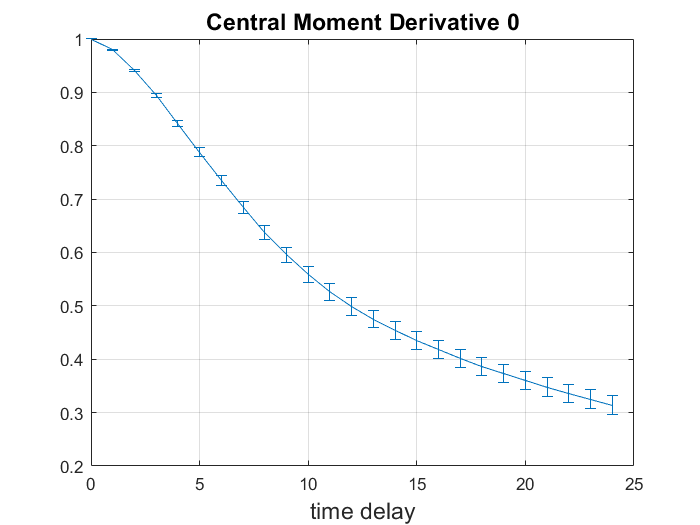

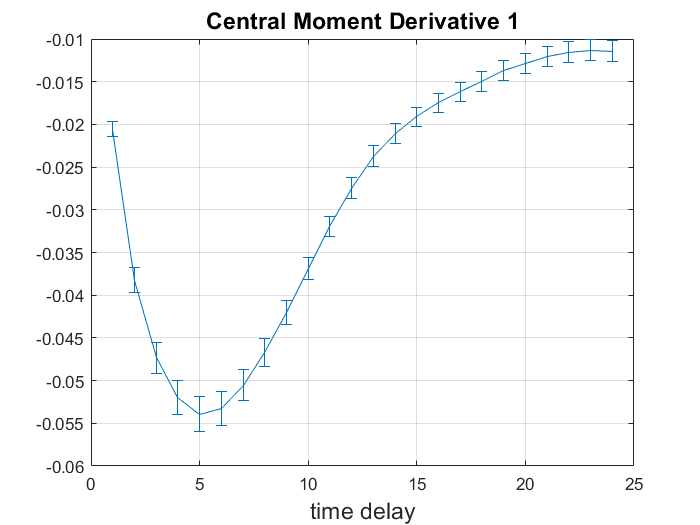

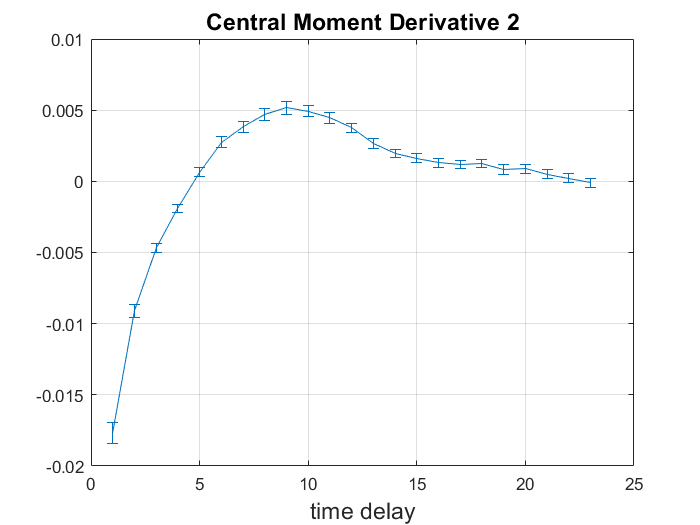

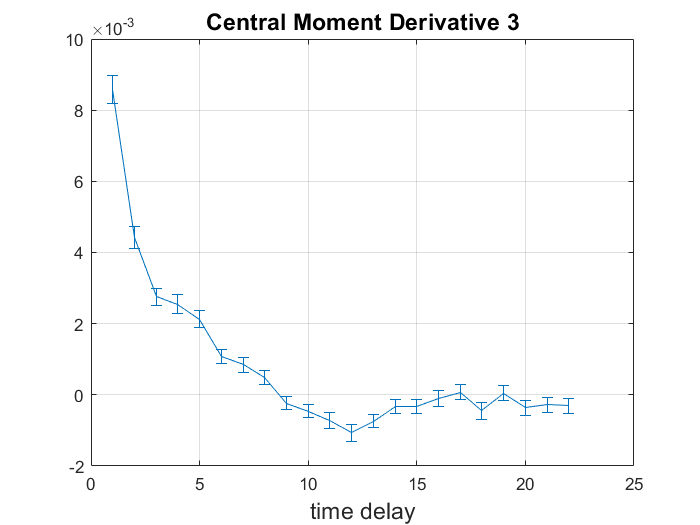

% run autocorrelation on subset of data attempt #3
% USE THIS

traces = {};
min_valid = 100; %60 (fluo3D2)
sum_all = zeros(1, 500);
sum_idx = zeros(1, 500);
min_kill = 20; %15 (fluo3D2)
min_val = 1000000; %1000000 (fluo3D2)
idx = 1;
cut = 0;
skip = 1;
max_delay = 25;
field = 'fluo3D2_interp';
for s = subset
    s.(field)(isnan(s.(field))) = 0;
    if sum(isnan(s.(field))) == 0 && s.inference_flag
        len = length(s.(field));
        trace = s.(field);
        if len >= min_valid
            splits = [1 find(trace < min_val) len];
            for i = 1:length(splits) - 1
                if splits(i + 1) - splits(i) <= min_kill
                    trace(splits(i):splits(i+1)) = 0;
                end
            end
            min_nonzero = find(trace > min_val, 1, 'first');
            max_nonzero = find(trace > min_val, 1, 'last');
            trace = trace(min_nonzero + cut:max_nonzero - cut);
            %trace = trace - mean(trace);
            %trace = trace(2:end) - trace(1:end- 1);
            len = length(trace);
            if length(find(trace > 0)) >= min_valid
                for k = 1:skip
                    traces{idx} = trace(k:skip:len);
                    idx = idx + 1;
                end
                sum_all(1:len) = sum_all(1:len) + trace;
                sum_idx(1:len) = sum_idx(1:len) + 1;
            end
        end
    end
end

gen_auto_cor(traces, 0:3, true, max_delay, 0);

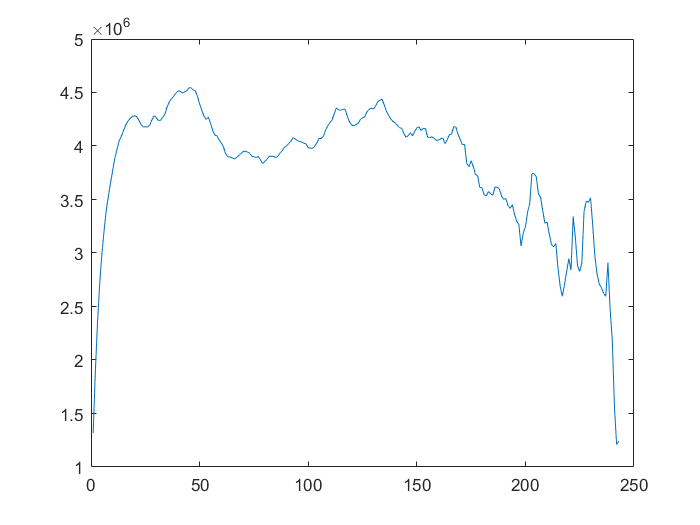


figure();
plot(sum_all ./ sum_idx)

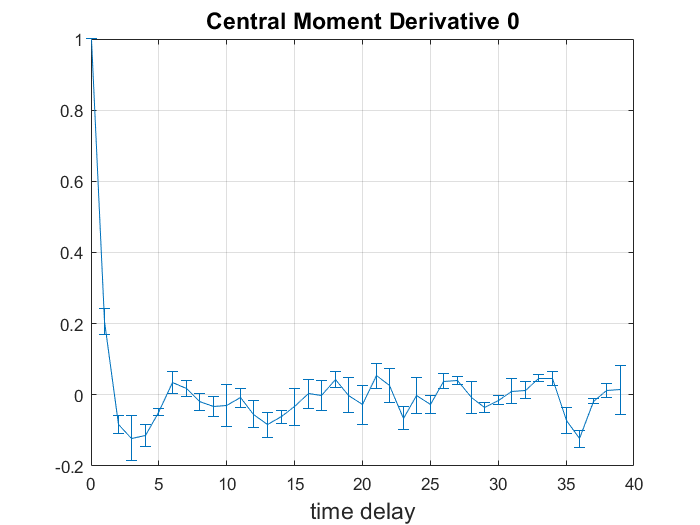

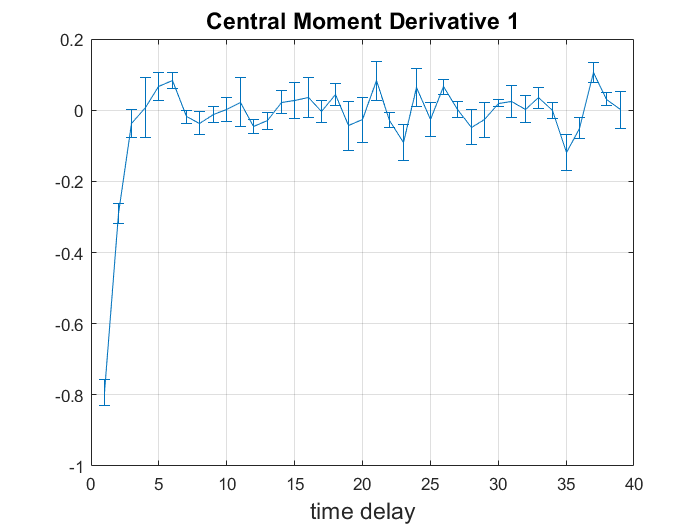

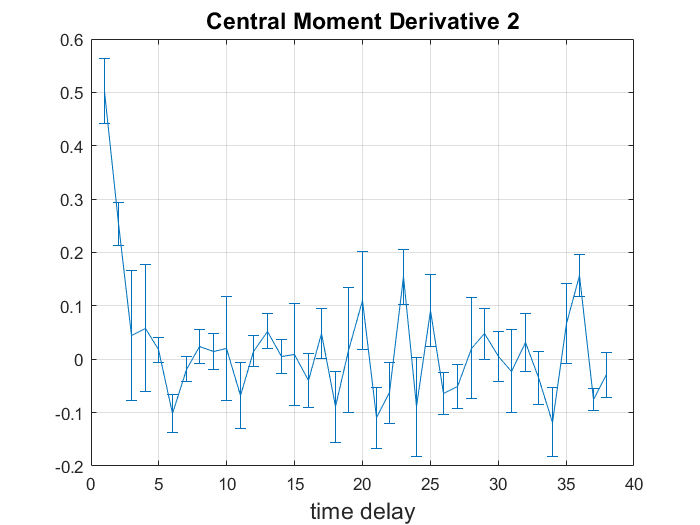

% attempt #4

% Run autocorrelation on subset of data
sum_all = zeros(1, 600);
idxes = zeros(1, 600);
traces = {};
min_trace = 100;
idx = 1;
cut = 0;
min_val = 300000; %1000000
max_zeroes = 3;
field = 'fluo3D_interp';
start_times= [];
for s = subset
    if sum(isnan(s.(field))) == 0 && s.inference_flag
        marks = find(s.(field) > min_val);
        start = marks(1);
        for i = 2:length(marks)
            if marks(i) - marks(i - 1) > max_zeroes
                if marks(i - 1) - start + 1 > min_trace + 2 * cut
                    first = start + cut;
                    last = marks(i-1) - cut;
                    traces{idx} = s.(field)(first:1:last);
                    traces{idx} = diff(traces{idx});
                    len = length(traces{idx});
                    sum_all(1:len) = sum_all(1:len) + traces{idx};
                    idxes(1:len) = idxes(1:len) + 1;
                    idx = idx + 1;
                end
                start = marks(i);
            end
        end
    end
end

gen_auto_cor(traces, 0:2, true, 40, 0);

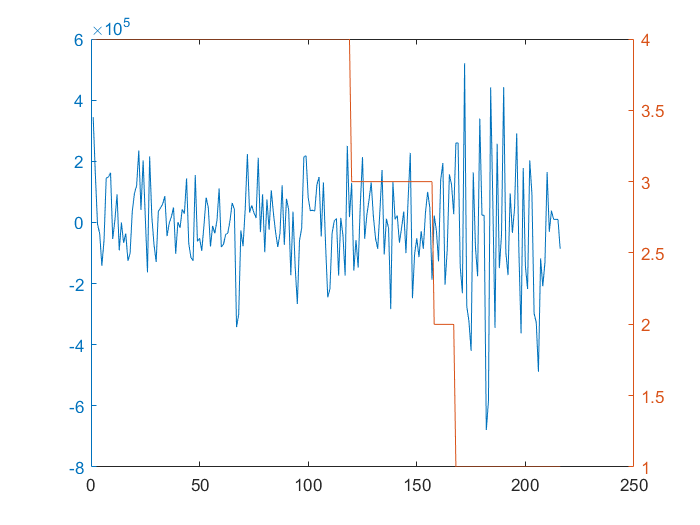


last_idx = find(idxes > 0, 1, 'last' );
sum_all = sum_all(1:last_idx) ./ idxes(1:last_idx);
figure();
yyaxis left
plot(sum_all)
yyaxis right
plot(idxes(1:last_idx))

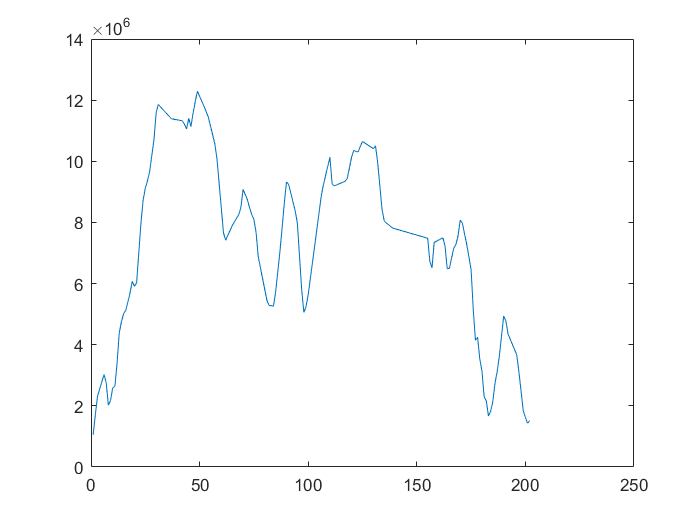

% show traces
i = 369;
figure();
%plot(subset(i).fluo3D_interp);
plot(traces{i});

%gen_auto_cor({traces{i:i+40}}, 0:3, false, 30, 0);

% curates traces for autocorrelation
new_traces = curate_traces(traces,0.7,5,10);
gen_auto_cor(new_traces, 0:3, true, 35, 0);

% Find distribution of first points

dist = [];
dist2 = [];
dist3 = [];
for t = 1:length(traces)
    trace = traces{t};
    dist = [dist trace(2)];
    dist2 = [dist2 trace];
    dist3 = [dist3 trace(2:end) - trace(1:end-1)];
end
figure();
histogram(dist);
figure();
histogram(dist2);
figure();
histogram(dist3);
avg = mean(dist2)
std(dist2)

% plot average fluorescence per ap bin for each construct

min_time = 900;
max_time = 1800;
thresh = 10;

ap_lim = 4;
ap_step = 2;
ap_bins = -ap_lim:ap_step:ap_lim;
sub_vals = zeros(3, length(ap_bins));
sub_stds = zeros(3, length(ap_bins));
subs = {sub1 sub2 sub3};
for i = 1:length(subs)
    sub = subs{i};
    set_vals = zeros(length(unique([sub.setID])), length(ap_bins));
    num_vals = zeros(size(set_vals));
    for set_num = unique([sub.setID])
        for ap_idx = 1:length(ap_bins)
            ap_val = ap_bins(ap_idx);
            sub_sub = sub([sub.setID] == set_num);
            sub_sub = sub_sub(abs([sub_sub.MeanAP] - ap_val) < ap_step / 2);
            all_times = [sub_sub.time_interp];
            all_fluo = [sub_sub.fluo3D_interp];
            idxes = all_times >= min_time & all_times <= max_time & all_fluo > thresh;
            if ~isempty(idxes)
                set_vals(set_num, ap_idx) = mean(all_fluo(idxes));
                num_vals(set_num, ap_idx) = length(idxes);
            end
        end
    end
    sub_vals(i,:) = sum(set_vals .* num_vals, 1) ./ sum(num_vals, 1);
    sub_stds(i,:) = std(set_vals, 0, 1);
end

figure();
for i = 1:3
    errorbar(ap_bins, sub_vals(i,:), sub_stds(i,:));
    hold on
end


% scatter plot of fluo as a function of ap

for i = 1:length(subs)
    sub = subs{i};
    for set_num = unique([sub.setID])
        sub_sub = sub([sub.setID] == set_num);
        all_aps = [];
        all_fluos = [];
        for j = 1:length(sub_sub)
            t_all = sub_sub(j).time_interp;
            new_idxes = find(t_all >= min_time & t_all <= max_time);
            all_aps = [all_aps ones(1, ...
                length(new_idxes)) * sub_sub(j).MeanAP];
            all_fluos = [all_fluos sub_sub(j).fluo3D_interp(new_idxes)];
        end
        figure();
        scatter(all_aps, all_fluos);
        title(['sub ' num2str(i) ' set ' num2str(set_num)]);
    end
end

% plot mean fluo versus trace length

min_val = 10;
for i = 1:length(subs)
    sub = subs{i};
    for set_num = unique([sub.setID])
        sub_sub = sub([sub.setID] == set_num);
        trace_lens = [];
        fluo_vals = [];
        for j = 1:length(sub_sub)
            new_fluos = sub_sub(j).fluo3D_interp(sub_sub(j).fluo3D_interp > min_val);
            fluo_vals = [fluo_vals mean(new_fluos)];
            trace_lens = [trace_lens length(new_fluos)];
        end
        figure();
        scatter(trace_lens, fluo_vals);
        title(['sub ' num2str(i) ' set ' num2str(set_num)]);
    end
end